## Import fatigue data

clear all
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_");

## Parameter estimation using MLE - Own implementation

% a = scale parameter
% b = shape parameter
% see matlab documentation on this distribution at https://www.mathworks.com/help/releases/R2025b/stats/weibull-distribution.html
% MLE - Own implementation
stress_levels = unique(data.ContactStressAmplitude_MPa_);
num_stress_levels = numel(stress_levels);
b_estimates = zeros(num_stress_levels, 1); % creates an array with num_stress_levels rows and 1 column to store the shape parameter estimates at each stress level
a_estimates = zeros(num_stress_levels, 1); % creates an array with num_stress_levels rows and 1 column to store the scale parameter estimates at each stress level
B1_lives_2PW = zeros(num_stress_levels, 1); % stores the calculated B1 life at each stress level

for i = 1:num_stress_levels

    life_i = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(i)); % extract the number of cycles for the current stress level
    num_observations_i = numel(life_i);

    % equations for parameter estimates for 2P Weibull
    g = @(beta)((num_observations_i / beta) + sum(log(life_i)) - (num_observations_i * sum((life_i .^ beta) .* log(life_i))/(sum(life_i .^ beta))));
    %g(1) % sanity check for anonymous function g, 1 is definitely not the
    %answer since it gave a non-zero anser
    %i
    b_est_MLE = fzero(g, 1); % root finding with an initial guess of 1
    g(b_est_MLE);
    a_est_MLE = (1/num_observations_i * sum(life_i.^ b_est_MLE)) ^ (1 / b_est_MLE);
    % store the parameter estimates at each stress level
    b_estimates(i) = b_est_MLE;
    a_estimates(i) = a_est_MLE;
    % Calculate the B1 prediction at each stress level using the parameter estimates from above
    B1_2PW = a_est_MLE * (-log(0.99)) ^ (1 / b_est_MLE);
    B1_lives_2PW(i) = B1_2PW;
end

% display the parameter estimates and B1 lives from own mle implementation

a_estimates

a_estimates = 1.0e+08 *

    3.5569
    1.3506
    0.6475
    0.3588


b_estimates

b_estimates =     1.0359
    1.0465
    1.1936
    0.7731


B1_lives_2PW

B1_lives_2PW = 1.0e+06 *

    4.1918
    1.6652
    1.3723
    0.0935


## Parameter estimation using MLE - MATLAB in-built 

% stres the matlab mle parameter estimates + B1 lives
b_estimates_matlab = zeros(num_stress_levels, 1);
a_estimates_matlab = zeros(num_stress_levels, 1);
B1_lives_matlab = zeros(num_stress_levels, 1);
% stores the MATLAB fitted distributions for later plotting
pd_2PW_all = cell(num_stress_levels, 1);

for i = 1:num_stress_levels
    life_i = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(i)); % extract the number of cycles for the current stress level
    % MLE - Verification using in-built MATLAB tools
    pd_2PW = fitdist(life_i, "Weibull");
    pd_2PW_all{i} = pd_2PW;
    a_estimates_matlab(i) = pd_2PW.ParameterValues(1);
    b_estimates_matlab(i) = pd_2PW.ParameterValues(2);
    B1_2PW_matlab = icdf(pd_2PW, 0.01);
    B1_lives_matlab(i) = B1_2PW_matlab;

end

% display the parameter estimates and B1 lives from matlab mle
a_estimates_matlab

a_estimates_matlab = 1.0e+08 *

    3.5569
    1.3506
    0.6475
    0.3588


b_estimates_matlab

b_estimates_matlab =     1.0359
    1.0465
    1.1936
    0.7731


B1_lives_matlab

B1_lives_matlab = 1.0e+06 *

    4.1918
    1.6652
    1.3723
    0.0935


## Compare the estimates from own implementation and MATLAB built-in

MLE_comparison = table(stress_levels, a_estimates, a_estimates_matlab, b_estimates, b_estimates_matlab, B1_lives_2PW, ...
    B1_lives_matlab,'VariableNames', {'Stress_MPa', 'Scale_Own_MLE', 'Scale_MATLAB_MLE', 'Shape_Own_MLE','Shape_MATLAB_MLE','B1_Own_MLE', 'B1_MATLAB_MLE'});
MLE_comparison

MLE_comparison = 4×7 table
    Stress_MPa    Scale_Own_MLE    Scale_MATLAB_MLE    Shape_Own_MLE    Shape_MATLAB_MLE    B1_Own_MLE    B1_MATLAB_MLE
    __________    _____________    ________________    _____________    ________________    __________    _____________

       4900        3.5569e+08         3.5569e+08           1.0359            1.0359         4.1918e+06     4.1918e+06  
       5500        1.3506e+08         1.3506e+08           1.0465            1.0465         1.6652e+06     1.6652e+06  
       6100        6.4751e+07         6.4751e+07           1.1936            1.1936         1.3723e+06     1.3723e+06  
       6700        3.5885e+07         3.5885e+07          0.77306           0.77306              93456          93456  


## PPLR and GoF (Anderson-Darling)

dF_tail =    -0.0071
    0.0222
    0.0314


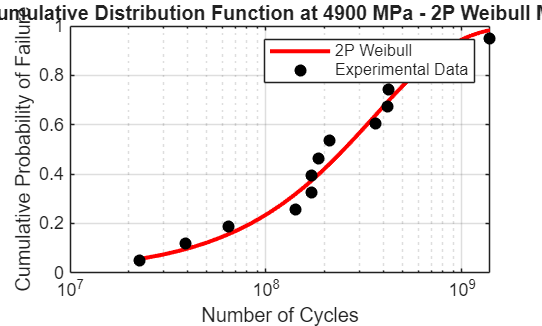

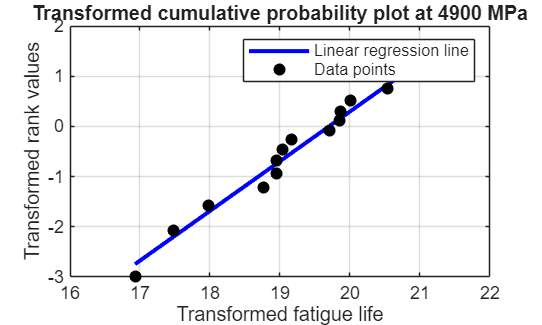

dF_tail =    -0.0070
    0.0226
    0.0314


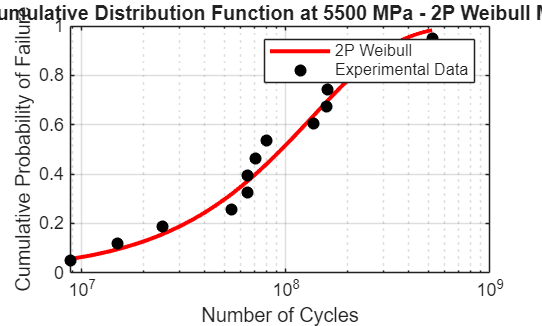

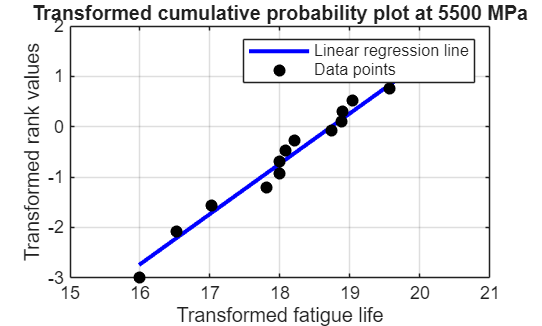

dF_tail =    -0.0069
    0.0226
    0.0320


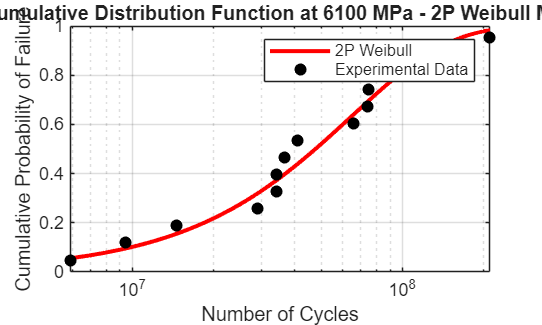

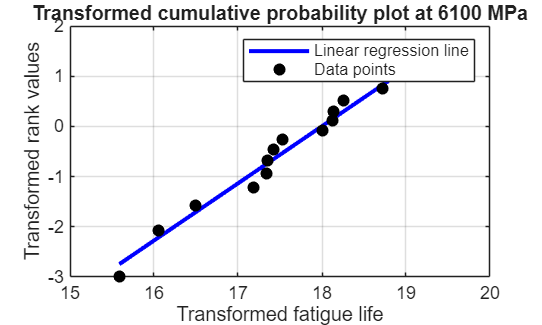

dF_tail =    -0.0389
   -0.0146
    0.0283


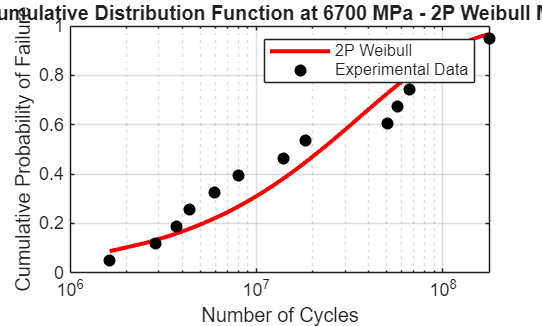

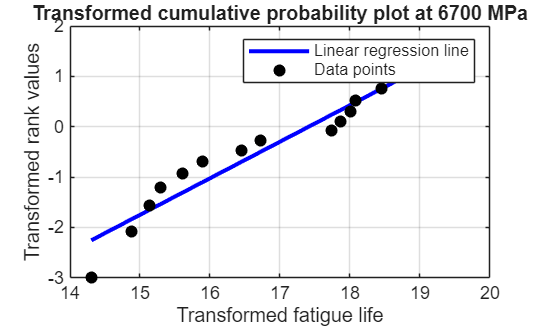

% PPLR
% Median rank plotting positions
% F_i = (i - 0.3)/(n + 0.4)

r_max_array = zeros(num_stress_levels, 1);
max_rank_eq = zeros(num_stress_levels, 2);
a_estimates_PPLR = zeros(num_stress_levels, 1);
b_estimates_PPLR = zeros(num_stress_levels, 1);
rank_equation = strings(num_stress_levels, 1);

% anderson-darling info
p = zeros(num_stress_levels, 1);
ad_test = zeros(num_stress_levels, 1);
ad_h = zeros(num_stress_levels, 1);
ad_cv = zeros(num_stress_levels, 1);

% stores the experimental plotting data and fitted CDFs for later plotting
cdf_x = cell(num_stress_levels, 1);
cdf_mle = cell(num_stress_levels, 1);
cdf_life_sorted = cell(num_stress_levels, 1);
cdf_empirical_F = cell(num_stress_levels, 1);

% stores tail-fit results at the 3 lowest fatigue lives
tail_fit_lives_W = cell(num_stress_levels, 1);
tail_fit_dF_W = cell(num_stress_levels, 1);
tail_fit_abs_dF_W = cell(num_stress_levels, 1);
tail_fit_F_empirical_W = cell(num_stress_levels,1);
tail_fit_dF_PPLR_W = cell(num_stress_levels,1);
tail_fit_abs_dF_PPLR_W = cell(num_stress_levels,1);
X_j_valid_all = cell(num_stress_levels, 1);
Y_j_all = cell(num_stress_levels, 1);
Y_fit_all = cell(num_stress_levels, 1);
for j = 1:num_stress_levels
    %j
    current_stress = stress_levels(j);
    life_j = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(j)); % extract the number of cycles for the current stress level
    num_observations_j = numel(life_j);
    life_j_sorted = sort(life_j); % sorts the lives in asending order
    X_j = log(life_j_sorted); % calculates the X values for the linearised 2P Weibull form
    observation_ranks = (1:num_observations_j)';

    % Median rank plotting positions
    F = (observation_ranks - 0.3) ./ (num_observations_j + 0.4);

    % Exclude invalid endpoint probabilities
    valid_positions = (F > 0) & (F < 1);
    F_mxg = F(valid_positions);
    X_j_valid = X_j(valid_positions);

    % Linearised 2P Weibull probabilities
    Y_j = log(-log(1 - F_mxg));

    % Calculate correlation coefficient
    r_2PW_matrix = corrcoef(X_j_valid, Y_j);
    max_r = r_2PW_matrix(1, 2);
    r_max_array(j) = max_r;
    rank_equation(j) = "Median Rank";
    
    % linear regression
    fitted_line = polyfit(X_j_valid, Y_j, 1);
    reg_slope = fitted_line(1);
    reg_intercept = fitted_line(2);
    b_est_PPLR = reg_slope;
    a_est_PPLR = exp(-reg_intercept / b_est_PPLR);
    % store the parameter estimates for PPLR
    a_estimates_PPLR(j) = a_est_PPLR;
    b_estimates_PPLR(j) = b_est_PPLR;

    % Plot the mle cdf and use the probability plotting from above for experimental data
    life_j_lin = linspace(min(life_j), max(life_j), 200);
    cdf_2PW_mle = 1 - exp(-(life_j_lin / a_estimates_matlab(j)) .^ b_estimates_matlab(j));

    % store the CDF data for later plotting
    cdf_x{j} = life_j_lin;
    cdf_mle{j} = cdf_2PW_mle;
    cdf_life_sorted{j} = life_j_sorted;
    cdf_empirical_F{j} = F_mxg;

    % Tail-fit check at the 3 lowest observed fatigue lives
    N_tail = life_j_sorted(1:3);
    F_empirical_tail = F(1:3);
    tail_fit_F_empirical_W{j} = F_empirical_tail;
    % difference between empirical and predicted cdfs using 2P Weibull mle parameters
    F_predicted_tail = 1 - exp(-(N_tail ./ a_estimates_matlab(j)) .^ b_estimates_matlab(j));
    dF_tail = F_empirical_tail - F_predicted_tail
    abs_dF_tail = abs(dF_tail);
    tail_fit_lives_W{j} = N_tail;
    tail_fit_dF_W{j} = dF_tail;
    tail_fit_abs_dF_W{j} = abs_dF_tail;

    % Tail-fit check using 2P Weibull PPLR parameter estimates
    F_predicted_tail_PPLR = 1 - exp( ...
        -(N_tail ./ a_estimates_PPLR(j)) .^ b_estimates_PPLR(j));

    dF_tail_PPLR = F_empirical_tail - F_predicted_tail_PPLR;
    abs_dF_tail_PPLR = abs(dF_tail_PPLR);

    % Store PPLR tail-fit differences
    tail_fit_dF_PPLR_W{j} = dF_tail_PPLR;
    tail_fit_abs_dF_PPLR_W{j} = abs_dF_tail_PPLR;

    % CDF plot 
    figure
    plot(life_j_lin, cdf_2PW_mle, 'Color', 'r', 'LineWidth', 2, 'LineStyle','-');
    hold on
    scatter(life_j_sorted(valid_positions), F_mxg, 'filled', 'o','k');
    xlabel('Number of Cycles');
    ylabel('Cumulative Probability of Failure');
    title(sprintf('Cumulative Distribution Function at %d MPa - 2P Weibull MLE', current_stress)); % got assitance on writing this line from chatgpt, recommended sprintf ** intially tried to concatenate which didn't work
    legend('2P Weibull', 'Experimental Data');
    set(gca,'xscale','log');
    grid on
    hold off

    % probability plot 
    % plot the regression to see transformed data against fitted line
    Y_fit = reg_slope * X_j_valid + reg_intercept;
    X_j_valid_all{j} = X_j_valid;
    Y_j_all{j} = Y_j;
    Y_fit_all{j} = Y_fit;

    figure
    plot(X_j_valid, Y_fit, 'Color', 'b', 'LineWidth', 2);
    hold on
    scatter(X_j_valid, Y_j, 'filled', 'o', 'k');
    xlabel('Transformed fatigue life');
    ylabel('Transformed rank values');
    title(sprintf('Transformed cumulative probability plot at %d MPa', current_stress));
    legend('Linear regression line', 'Data points');
    grid on
    hold off

    % conduct an anderson-darling GoF test
    clear adtest % adtest got initialised as a variable for some reason, this clears it to avoid errors
    [h, p_value, test_stat, cv] = adtest(life_j,"Distribution","weibull"); % for unspecified parameters for the weibull distribution, returns h (rejects or accepts the null hypothesis, p-value, the test statistic ad the critical value
    p(j) = p_value;
    ad_test(j) = test_stat;
    ad_h(j) = h;
    ad_cv(j) = cv;

end

Create a single panel with all PPLR plots 

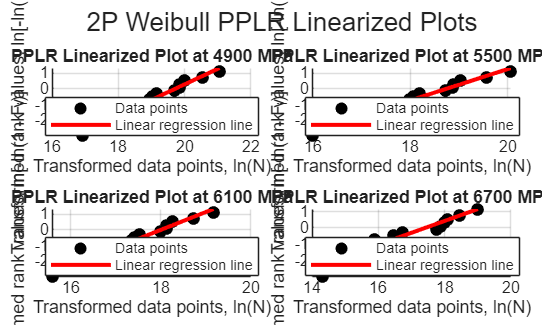


figure('Name','2P Weibull PPLR Linearized Plots');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for j = 1:num_stress_levels
    nexttile
    scatter(X_j_valid_all{j}, Y_j_all{j}, 40, 'k', 'filled');
    hold on;
    plot(X_j_valid_all{j}, Y_fit_all{j}, 'r-', 'LineWidth', 2);
    xlabel('Transformed data points, ln(N)');
    ylabel('Transformed rank values, ln[-ln(1 - F_i)]');
    title(sprintf('PPLR Linearized Plot at %d MPa', stress_levels(j)));
    legend('Data points', 'Linear regression line', 'Location','best');
    grid on;
    hold off;
end
sgtitle('2P Weibull PPLR Linearized Plots');

## Check between MATLAB MLE parameter estimates  and PPLR parameter estimates 

% Calculate the percentage difference between MATLAB MLE and PPLR estimates
a_percent_difference = abs(a_estimates_matlab - a_estimates_PPLR) ./ abs(a_estimates_matlab) * 100

a_percent_difference =     1.0832
    1.0836
    0.9587
    1.2321


b_percent_difference = abs(b_estimates_matlab - b_estimates_PPLR) ./ abs(b_estimates_matlab) * 100

b_percent_difference =     4.4199
    4.4882
    4.5365
    6.0636


% display the B1 predictions from PPLR
B1_lives_PPLR = a_estimates_PPLR .* (-log(0.99)) .^ (1 ./ b_estimates_PPLR)

B1_lives_PPLR = 1.0e+06 *

    3.4506
    1.3691
    1.1536
    0.0644


## Export analysis results to separate MATLAB file 

This is done to combine plots and do cross analysis for the Results section

% the section of code below was gotten from ChatGPT 
save('results_2PW_Steel.mat', ...
    'stress_levels', ...
    'a_estimates', ...
    'b_estimates', ...
    'B1_lives_2PW', ...
    'a_estimates_matlab', ...
    'b_estimates_matlab', ...
    'B1_lives_matlab', ...
    'a_estimates_PPLR', ...
    'b_estimates_PPLR', ...
    'B1_lives_PPLR', ...
    'a_percent_difference', ...
    'b_percent_difference', ...
    'r_max_array', ...
    'rank_equation', ...
    'ad_h', ...
    'p', ...
    'ad_test', ...
    'ad_cv', ...
    'cdf_x', ...
    'cdf_mle', ...
    'cdf_life_sorted', ...
    'cdf_empirical_F', ...
    'tail_fit_F_empirical_W', ...
    'tail_fit_dF_PPLR_W', ...
    'tail_fit_abs_dF_PPLR_W', ...
    'pd_2PW_all', 'tail_fit_lives_W', 'tail_fit_dF_W', 'tail_fit_abs_dF_W');
